# bwgraph() Examples

If you are unable to run this live script, please see *examples.pdf* instead.

## Example 1

Construct a graph of the connected non-zero pixels in a black and white image (2D matrix). Use a connectivity of 4, meaning that pixels with touching edges are connected, but not those with touching corners. Overlay the graph onto the image for visualisation.

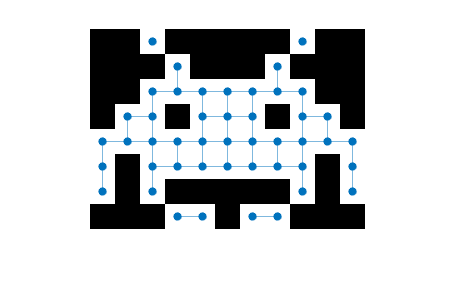

im = [ 0 0 1 0 0 0 0 0 1 0 0; 0 0 0 1 0 0 0 1 0 0 0; 0 0 1 1 1 1 1 1 1 0 0;
       0 1 1 0 1 1 1 0 1 1 0; 1 1 1 1 1 1 1 1 1 1 1; 1 0 1 1 1 1 1 1 1 0 1;
       1 0 1 0 0 0 0 0 1 0 1; 0 0 0 1 1 0 1 1 0 0 0];
% Construct the graph of connected non-zero pixels, with a connectivity of 4. 
G = bwgraph( im, Connectivity=4 );
% Remove nodes which are zero in the image, as these cannot be connected.
G = rmnode( G, find( ~im ) );
% Plot the image and graph.
figure
imshow( im, [], 'InitialMagnification', 2500 )
hold on
[ Y, X ] = ind2sub( size( im ), find( im ) );
plot( G, 'XData', X(:), 'YData', Y(:), 'NodeLabel', [] );

## Example 2

Find the shortest path between 2 points on a black and white image (2D logical matrix).

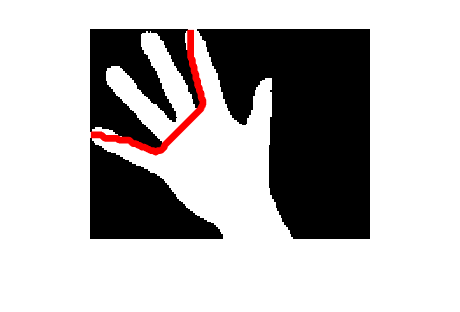

im = imresize( imread( 'hands1-mask.png' ), 0.5 );
% Construct the graph of connected non-zero pixels.
G = bwgraph( im );
% Calculate the linear indices of the start and end pixels, which are 
% used to reference the respective node in G.
sz = size( im );
source = sub2ind( sz, 61, 1 );
target = sub2ind( sz, 1, 58 );
% Find the shortest path between the 2 nodes.
P = shortestpath( G, source, target );
% Calculate the respective pixels for each node in the path.
[ Pi, Pj ] = ind2sub( sz, P );
% Plot the image and path.
figure
imshow( im, [], 'InitialMagnification', 175 )
hold on
plot( Pj, Pi, 'r-', 'LineWidth', 4 )

## Example 3

Find the central path, i.e., centerline, of a volume (3D logical matrix). Node weights are used to prioritise voxels which are further from the volume boundary.

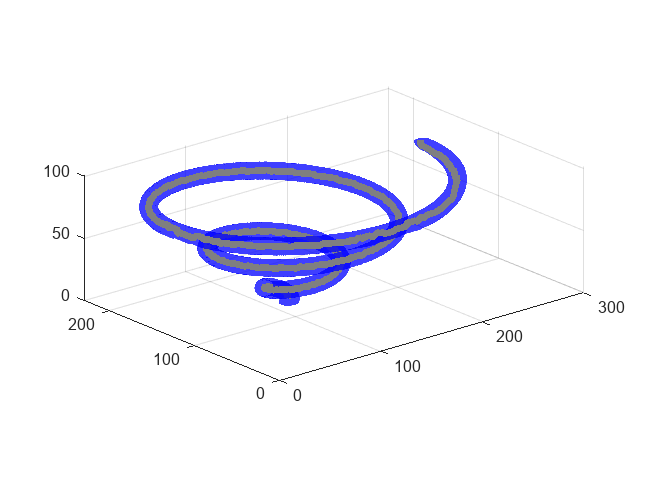

load( 'spiralVol.mat' )
spiralVol = imresize3( spiralVol, 0.5 );
% bwdist gives the distance between each between each voxel and its 
% nearest nonzero voxel. This is used to weight nodes and therefore find
% a central path.
spiralVol = padarray( spiralVol, [1 1 1] );
distanceFromBoundary = bwdist( ~spiralVol );
% Invert the distances, so that the lowest weights are at the center.
weights = max( distanceFromBoundary(:) ) - distanceFromBoundary;
% Construct the graph of connected non-zero voxels, with their 
% assosciated weights.
G = bwgraph( spiralVol, NodeWeights=weights );
% Find the shortest path between 2 voxels, considering the node weights.
sz = size( spiralVol );
source = sub2ind( sz, 124, 112, 5 );
target = sub2ind( sz, 125, 244, 101 );
P = shortestpath( G, source, target );
[ Pi, Pj, Pk ] = ind2sub( sz, P );
% Plot the volume and path.
figure
axes( 'NextPlot', 'add', 'DataAspectRatio', [1 1 1], ...
    'View', [-40 20], 'XGrid', 'on', 'YGrid', 'on', 'ZGrid', 'on')
patch( isosurface( spiralVol ), ...
    'FaceColor', 'b', 'EdgeColor', 'none', 'FaceAlpha', 0.5 )
plot3( Pj, Pi, Pk, 'y-', 'LineWidth', 4 )